startTime = datetime(2025,6,28,0,0,0);
stopTime = startTime + seconds(5*7.255*10^3);
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);

Add satellite scenario

sat = satellite(sc,"threeSatelliteConstellation.tle");

Display satellite scenario and also plot their groundTracks over 20 minutes.

% show(sat)
groundTrack(sat,"LeadTime",1200);

Display the orbital elements of each satellite in the constellation!

ele1 = orbitalElements(sat(1));
ele2 = orbitalElements(sat(2));
ele3 = orbitalElements(sat(3));

Return the geographic coordinates of the first satellite at time 6/28/2025 03:30:00 PM UTC

% time = datetime(2025,6,28,3,30,0);
% pos = states(sat(1),time,"CoordinateFrame","geographic");

Add Ground Stations, one is the Department of Informatics and Telecomuunications in Lamia, Greece and the other is the Canberra Deep Space Communications Complexes.

name = ["Department of Informatics and Telecommunications", ...
        "Canberra Deep Space Communications Complex"];
lat = [38.875941904578895, -35.40139];
lon = [22.437526584061686, 148.98167];
gs = groundStation(sc, "Name",name,"Latitude",lat,...
    "Longitude",lon);

Return azimuth angle, elevation angle and range at specified time

time = startTime;
elevations = [];
ranges = [];
time_axis = [];
alts = [];
while time ~= stopTime
    [az,el,r] = aer(gs(1),sat(1),time);
    time_axis = [time_axis time];
    elevations = [elevations el];
    ranges = [ranges r];
    time = time + seconds(1);
end
positions = states(sat(1),'CoordinateFrame','geographic');
alts = positions(3,:);

Play the satellite scenario with the satellites and ground stations

% play(sc)

Plot the elevation angles per time

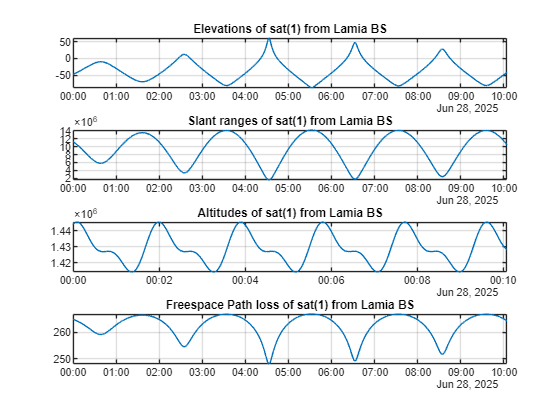

%   calculate the altitude of each elevation
subplot(4,1,1);
plot(time_axis,elevations);
title('Elevations of sat(1) from Lamia BS');
grid on;
axis tight;
subplot(4,1,2);
plot(time_axis,ranges);
grid on;
axis tight;
title('Slant ranges of sat(1) from Lamia BS')
subplot(4,1,3);
time_axis2 = sc.StartTime + seconds(0:length(alts)-1);  % Time vector
plot(time_axis2,alts);
grid on;
axis tight;
title('Altitudes of sat(1) from Lamia BS')

% Calculate pathloss for each slant range
fc = 30e3; % 30 GHz
FSPL = 34.45 + 20*log10(ranges) + 20*log10(fc);
subplot(4,1,4);
plot(time_axis, FSPL);
grid on;
axis tight;
title('Freespace Path loss of sat(1) from Lamia BS');